# PS5: Filters in Series

### By Ari Porad on March 25th, 2021

### For Olin College's *Introduction to Sensors, Instrumentation, and Measurement* Spring 2021

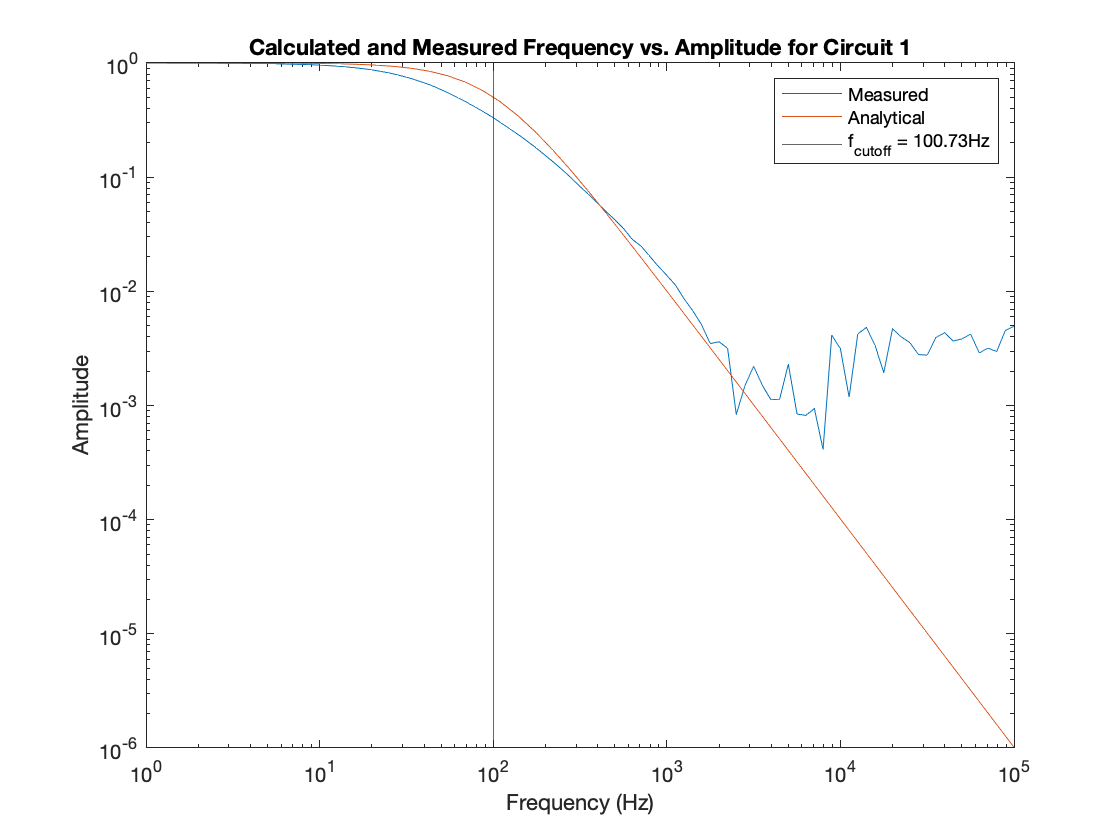

R = 1580;    % 1.58 kOhms
C = 10 ^ -6; % 1 MF

cutoff_freq = 1 / (2 .* pi .* R .* C);

process_data(1, cutoff_freq, @(f) calc_lowpass_amplitude(1580, 10 ^ -6, f) .^ 2)

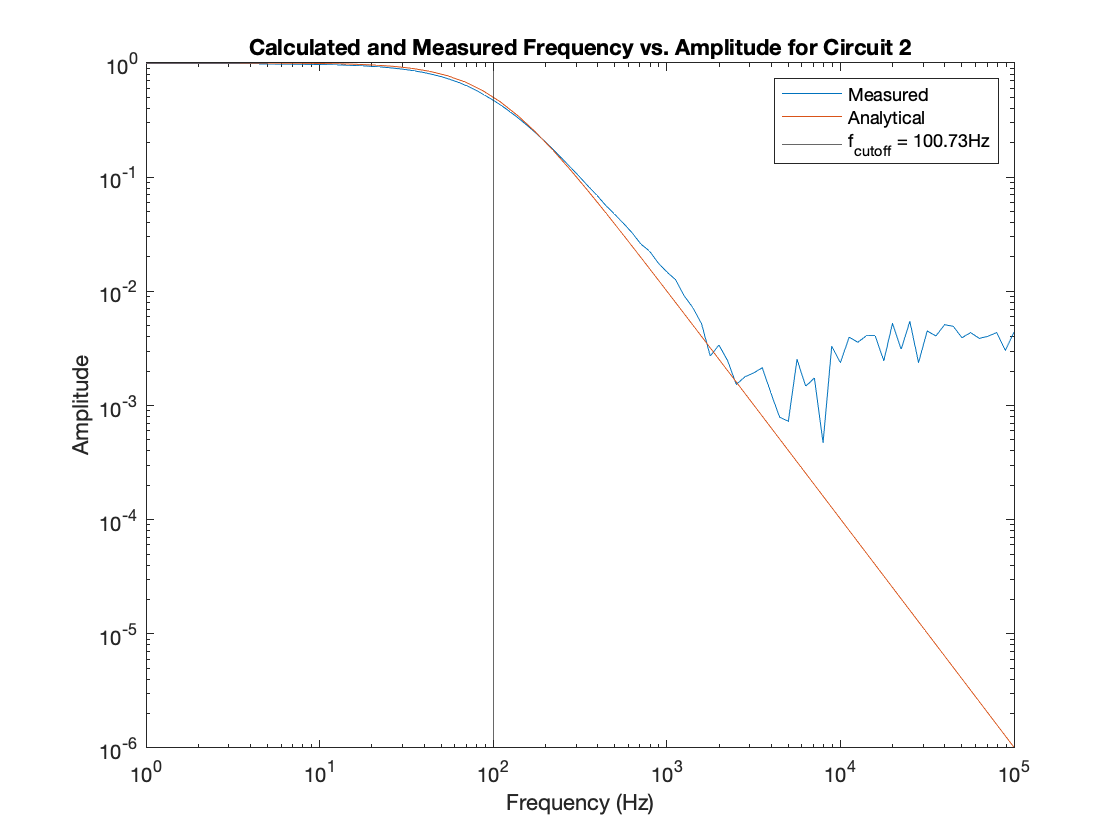

process_data(2, cutoff_freq, @(f) calc_lowpass_amplitude(1580, 10 ^ -6, f) .^ 2)

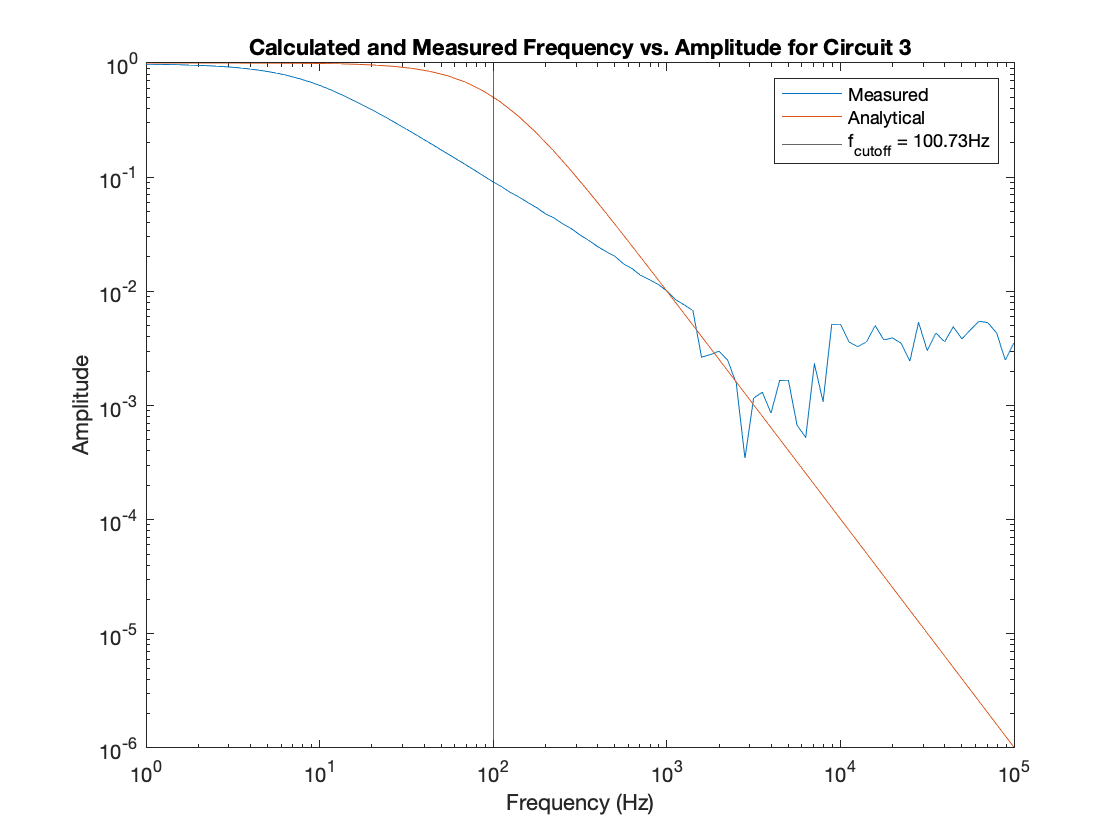

process_data(3, cutoff_freq, @(f) calc_lowpass_amplitude(1580, 10 ^ -6, f) .^ 2)

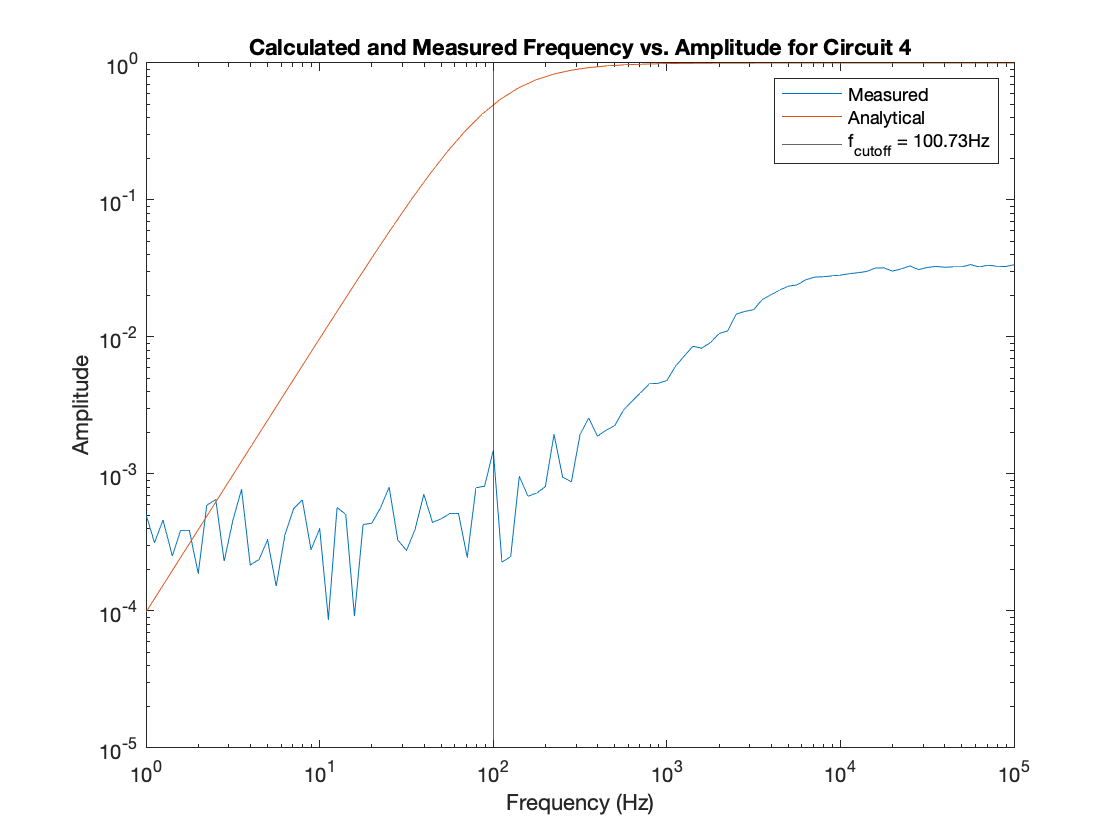

process_data(4, cutoff_freq, @(f) calc_highpass_amplitude(1580, 10 ^ -6, f) .^ 2)

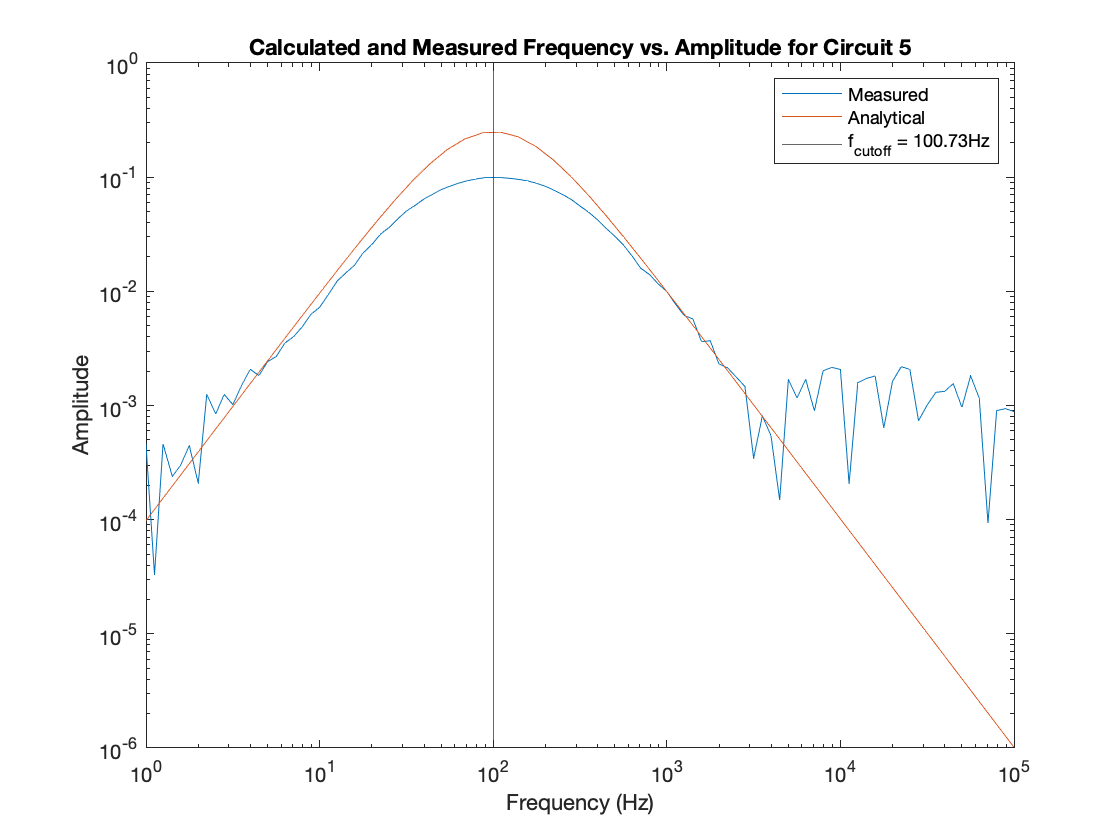

process_data(5, cutoff_freq, @(f) ( ...
    calc_lowpass_amplitude(1580, 10 ^ -6, f) .^ 2) .* ...
    (calc_highpass_amplitude(1580, 10 ^ -6, f) .^ 2) ...
)

For all circuits, the filter consistently drops to an output amplitude of roughly 10^-3 (from an input amplitude of 10^0) at one order of magnitude away from the cutoff frequency (above for Circuits 1, 2, and 3; below for Circuit 4; and on either side for Circuit 5). All circuits have their output amplitudes start to drop slightly just before their cutoff frequencies.

function process_data(circuit_num, cutoff_freq, calc_amp)
    data = readmatrix(sprintf("circuit_%1.0f_bode.csv", circuit_num));
    m_freq = data(:, 1);
    m_gain = data(:, 2);
    m_phase = data(:, 3);
    
    m_amp = amplitude_from_dB(m_gain);
    
    c_freq = logspace(0, 5);
    c_amp = calc_amp(c_freq);
    
    figure(circuit_num);
    
    loglog(m_freq, m_amp); hold on;
    loglog(c_freq, c_amp);
    xline(cutoff_freq);
    
    title(sprintf("Calculated and Measured Frequency vs. Amplitude for Circuit %1.0f", circuit_num));
    xlabel("Frequency (Hz)");
    ylabel("Amplitude");
    legend("Measured", "Analytical", sprintf("f_{cutoff} = %1.2fHz", cutoff_freq));
    
    hold off;
    
end

function A = amplitude_from_dB(dB)
    A = 10 .^ (dB ./ 20);
end

function A = calc_lowpass_amplitude(R, C, f) % CR
    A = 1 ./ sqrt(1 + (R .* C .* 2 .* pi .* f) .^ 2);
end


function A = calc_highpass_amplitude(R, C, f) % CR
    A = (2 .* pi .* f .* R .* C) ./ sqrt(1 + (R .* C .* 2 .* pi .* f) .^ 2);
end